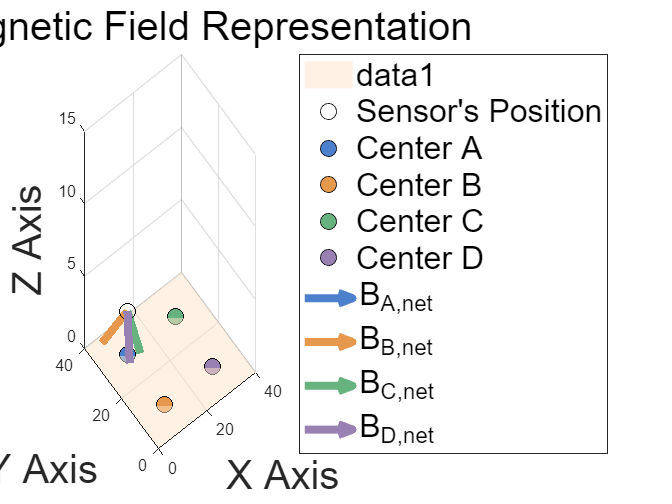

% 数据定义
% 网格板大小
x_range = 0:5:40;
y_range = 0:5:40;

[X, Y] = meshgrid(x_range, y_range); % 网格点坐标
Z = zeros(size(X)); % 网格板在 z = 0 平面

% 传感器位置
sensor_pos = [10, 30, 3];

% 线圈中心位置
coil_centers = [
    10, 30, 0; % Coil A
    10, 10, 0; % Coil B
    30, 30, 0; % Coil C
    30, 10, 0; % Coil D
];
coil_colors = {[0.3, 0.5, 0.8], [0.9, 0.6, 0.3], [0.4, 0.7, 0.5], [0.6, 0.5, 0.7]}; % 线圈颜色

% 矢量定义
B_no_coil = [0, 0, 1]; % 蓝色箭头，B_no-coil
B_net = [
    75.0787, 57.9764, -84.8120; % BA_net
    -186.4059, 335.4354, -125.3279; % BB_net
    119.7497, -73.6566, -97.6628; % BC_net
    -376.2632, -538.2038, 6.7634; % BD_net
];

% 绘图
figure;
hold on;

% 绘制网格板
surf(X, Y, Z, 'FaceAlpha', 0.5, 'EdgeColor', 'none', 'FaceColor', [1, 0.9, 0.8]);

% 绘制传感器位置
plot3(sensor_pos(1), sensor_pos(2), sensor_pos(3), 'ko', 'MarkerSize', 10, 'DisplayName', "Sensor's Position");

% 绘制线圈中心
for i = 1:size(coil_centers, 1)
    plot3(coil_centers(i, 1), coil_centers(i, 2), coil_centers(i, 3), 'o', ...
        'MarkerSize', 10, 'MarkerFaceColor', coil_colors{i}, 'MarkerEdgeColor', 'k', ...
        'DisplayName', ['Center ', char('A' + i - 1)]);
end

% 绘制矢量
% quiver3(sensor_pos(1), sensor_pos(2), sensor_pos(3), B_no_coil(1), B_no_coil(2), B_no_coil(3), ...
%     'b', 'LineWidth', 5, 'MaxHeadSize', 0.5, 'DisplayName', 'B_{no-coil}');

for i = 1:size(B_net, 1)
    quiver3(sensor_pos(1), sensor_pos(2), sensor_pos(3), B_net(i, 1), B_net(i, 2), B_net(i, 3), ...
        'Color', coil_colors{i}, 'LineWidth', 5, 'MaxHeadSize', 0.5, ...
        'DisplayName', ['B_{', char('A' + i - 1), ',net}']);
end

% 设置图例
legend('Location', 'northeastoutside','FontSize', 20);

% 设置轴标签和范围
xlabel('X Axis','FontSize', 25);
ylabel('Y Axis','FontSize', 25);
zlabel('Z Axis','FontSize', 25);
xlim([0, 40]);
ylim([0, 40]);
zlim([0, 15]);

% 设置标题
title('3D Magnetic Field Representation','FontSize', 25);

% 设置视角
view(3);
grid on;
hold off;